## Polynomial 1

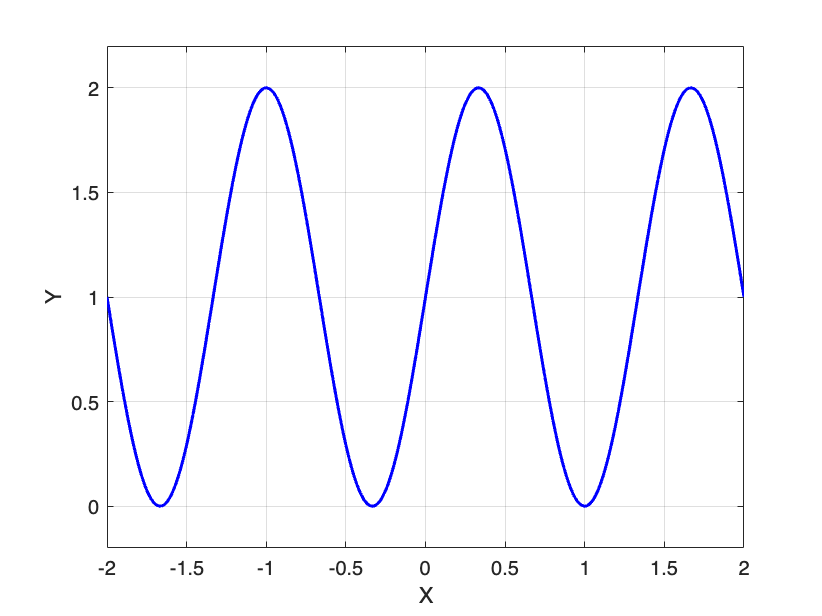

clc
clear all

polynomial1 = readmatrix("polynomials/Polinomio1.txt");
plotPolynomial(polynomial1);

% Hyperparameters
S_1 = 5; % <= 16
S_2 = 14; % <= 14
S_3 = 10; % <= 10 only for P4 & P5
layers = [1 S_1 1];
transferFuncs = [2 1];

% Create MLP network
polynomial1_mlp = mlpNetwork(layers, transferFuncs);
disp('MLP created successfully')

MLP created successfully


% Load previous Weights and Biases training values
polynomial1_mlp = loadWeightsAndBiases(polynomial1_mlp, 'trainPolynomial1');

% Load previous Error History
polynomial1_mlp = loadErrorHistory(polynomial1_mlp, 'trainPolynomial1');

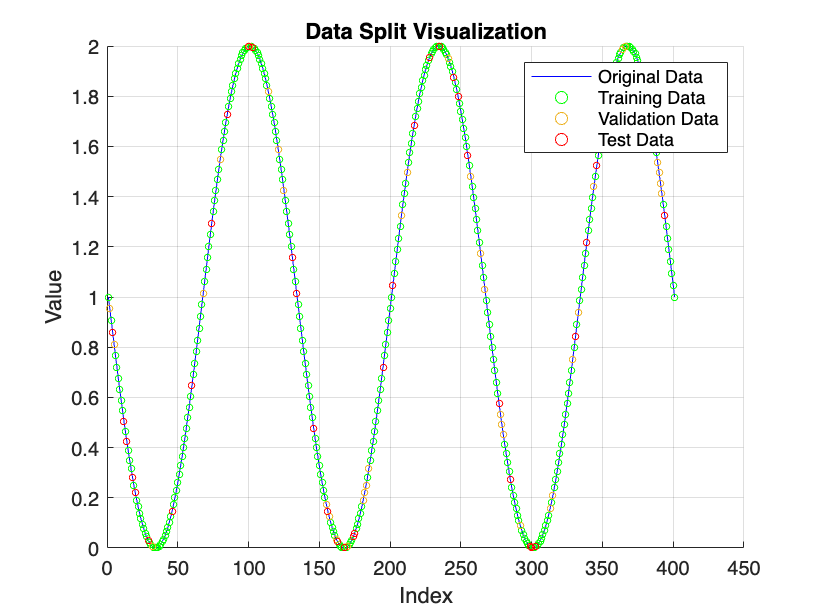

% Get data sets
[trainSet, valSet, testSet] = polynomial1_mlp.generateSets(polynomial1);

% Train MLP network
maxEpochs = 5000;           % Maximum number of epochs
learningRate = 1e-3;        % Delta value 1e-2 to 1e-5
errorTrain = 1e-4;          % Accuracy
epochVal = maxEpochs*0.1;   % How many epochs during the learning process will be a validation
numVal = 5;                 % The number of consecutive increments of validation error validation error to trigger early stopping
numberOfBatches = 50;      % Number of batches to train

batch = 1;                  % Batch number
stopCode = 0;               % Code indicating early stopping
while (stopCode ~= 1 && batch <= numberOfBatches)
    [polynomial1_mlp, stopCode] = polynomial1_mlp.train( ...
        trainSet, ...
        valSet, ...
        learningRate, ...
        maxEpochs, ...
        errorTrain, ...
        epochVal, ...
        numVal...
    );
    batch = batch + 1;
end

saveWeightsAndBiases(polynomial1_mlp, 'trainPolynomial1');

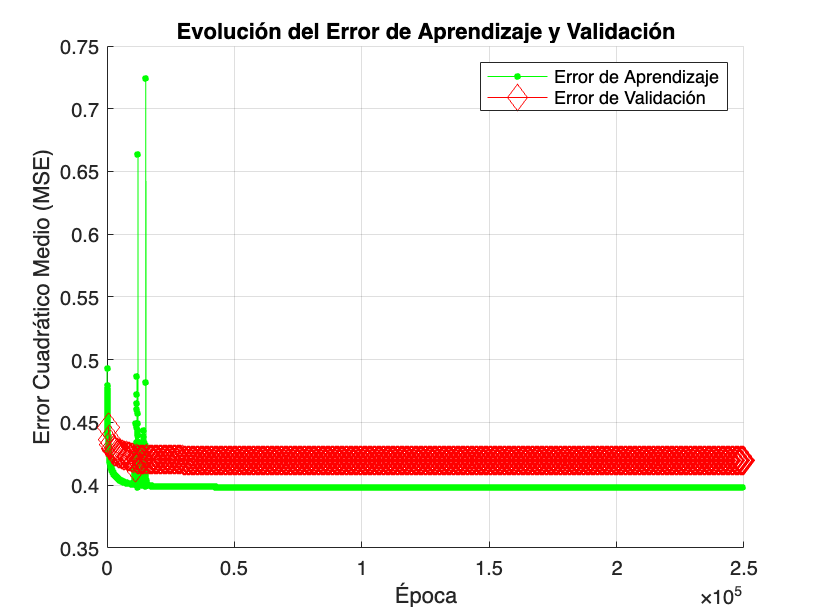

% Plot error
polynomial1_mlp.graphErroHistory(epochVal);

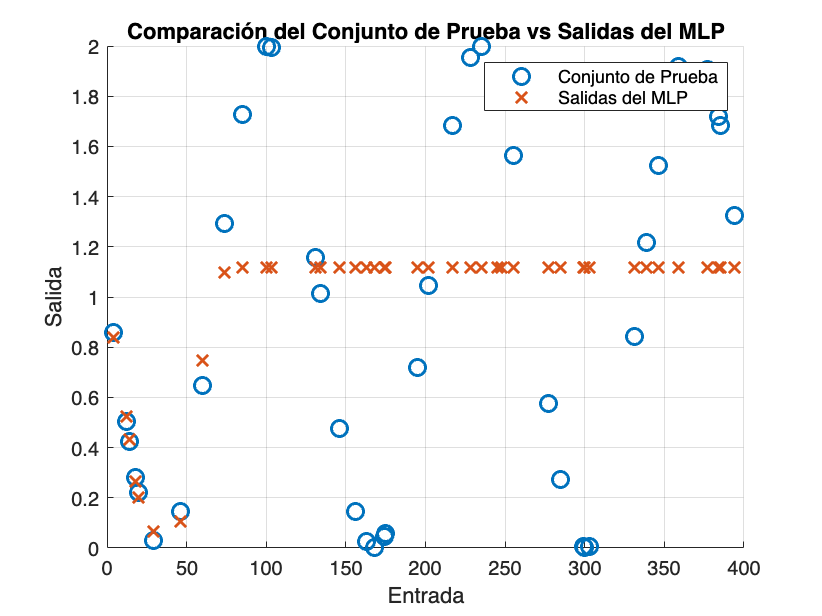

% Plot test
polynomial1_mlp.graphTestSet(testSet);

### Polynomial 2

clc
clear all

polynomial2 = readmatrix("polynomials/Polinomio2.txt");
plotPolynomial(polynomial2);

% Hyperparameters
S_1 = 12; % <= 16
S_2 = 9; % <= 14
layers = [1 S_1 S_2 1];
transferFuncs = [2 2 1];

% Create MLP network
polynomial2_mlp = mlpNetwork(layers, transferFuncs);
disp('MLP created successfully')

% Load previous Weights and Biases training values
polynomial2_mlp = loadWeightsAndBiases(polynomial2_mlp, 'trainPolynomial2');

% Load previous Error History
polynomial2_mlp = loadErrorHistory(polynomial2_mlp, 'trainPolynomial2');

% Get data sets
[trainSet, valSet, testSet] = polynomial2_mlp.generateSets(polynomial2);

% Train MLP network
maxEpochs = 5000;           % Maximum number of epochs
learningRate = 1e-5;        % Delta value 1e-2 to 1e-5
errorTrain = 1e-4;          % Accuracy
epochVal = maxEpochs*0.1;   % How many epochs during the learning process will be a validation
numVal = 5;                 % The number of consecutive increments of validation error validation error to trigger early stopping
numberOfBatches = 100;      % Number of batches to train

batch = 1;                  % Batch number
stopCode = 0;               % Code indicating early stopping
while (stopCode ~= 1 && batch <= numberOfBatches)
    [polynomial2_mlp, stopCode] = polynomial2_mlp.train( ...
        trainSet, ...
        valSet, ...
        learningRate, ...
        maxEpochs, ...
        errorTrain, ...
        epochVal, ...
        numVal...
    );
    batch = batch + 1;

    saveWeightsAndBiases(polynomial2_mlp, 'trainPolynomial2');
end
disp('Training batch complete.')

% Plot error
polynomial2_mlp.graphErroHistory(epochVal);

% Plot test
polynomial2_mlp.graphTestSet(testSet);

## Polynomial 3

clc
clear all

polynomial3 = readmatrix("polynomials/Polinomio3.txt");
plotPolynomial(polynomial3);



% Hyperparameters
S_1 = 8; % <= 16
S_2 = 12; % <= 14
S_3 = 10; % <= 10
layers = [1 S_1 S_2 1];
transferFuncs = [2 2 1];

% Create MLP network
polynomial3_mlp = mlpNetwork(layers, transferFuncs);
disp('MLP created successfully')



% Load previous Weights and Biases training values
polynomial3_mlp = loadWeightsAndBiases(polynomial3_mlp, 'trainPolynomial3');

% Load previous Error History
polynomial3_mlp = loadErrorHistory(polynomial3_mlp, 'trainPolynomial3');



% Get data sets
[trainSet, valSet, testSet] = polynomial3_mlp.generateSets(polynomial3);


% Train MLP network
maxEpochs = 3000; % Maximum number of epochs
learningRate = 1e-3; % Delta value 1e-2 to 1e-5
errorTrain = 1e-4; % Accuracy
epochVal = 10; % How many epochs during the learning process will be a validation
numVal = 5; % The number of consecutive increments of validation error validation error to trigger early stopping
numberOfRetries = 1000; % If training faill retry n times
stopCode = 0;
ntry = 0;

while (stopCode ~= 1 && ntry < numberOfRetries)
    fprintf('%d %%\n', ntry * 100 / numberOfRetries);
    [polynomial3_mlp, stopCode] = polynomial3_mlp.train( ...
        trainSet, ...
        valSet, ...
        learningRate, ...
        maxEpochs, ...
        errorTrain, ...
        epochVal, ...
        numVal...
    );
    ntry = ntry + 1;

    saveWeightsAndBiases(polynomial3_mlp, 'trainPolynomial3');
end
disp('100% Training batch complete.')

% Plot error
polynomial3_mlp.graphErroHistory(epochVal);

% Plot test
polynomial3_mlp.graphTestSet(testSet);

### Functions

function plotPolynomial(data)
    x = data(:, 1);
    y = data(:, 2);

    figure;
    plot(x, y, 'b-', 'LineWidth', 1.5);
    grid on;
    xlabel('X');
    ylabel('Y');

    %xPadding = (max(x) - min(x)) * 0.1; % 10% padding X
    yPadding = (max(y) - min(y)) * 0.1; % 10% padding Y
    %xlim([min(x) - xPadding, max(x) + xPadding]);
    ylim([min(y) - yPadding, max(y) + yPadding]);
end

function saveWeightsAndBiases(mlp, path)  
    % Write weights
    for i = 1:length(mlp.Weights)
        filename = fullfile(path, sprintf('weightsLayer%d.txt', i));
        writematrix(mlp.Weights{i}, filename);
    end
    
    % Write bias
    for i = 1:length(mlp.Biases)
        filename = fullfile(path, sprintf('biasesLayer%d.txt', i));
        writematrix(mlp.Biases{i}, filename);
    end

    % Write Error History
    writematrix(mlp.TrainingErrorHistory, fullfile(path, 'trainingErrorHistory.txt'));
    writematrix(mlp.ValidationErrorHistory, fullfile(path, 'validationErrorHistory.txt'));
end

function mlp = loadWeightsAndBiases(mlp, path)
    % Verify first if there is previous training data
    if ~isfolder(path)
        return;
    end
    
    num_layers = length(mlp.Weights);
    weights = cell(num_layers, 1);
    biases = cell(num_layers, 1);
    
    % Load Weights
    for i = 1:num_layers
        filename = fullfile(path, sprintf('weightsLayer%d.txt', i));
        if isfile(filename)
            weights{i} = readmatrix(filename);
        else
            return
        end
    end
    
    % Load Biases
    for i = 1:num_layers
        filename = fullfile(path, sprintf('biasesLayer%d.txt', i));
        if isfile(filename)
            biases{i} = readmatrix(filename);
        else
            return
        end
    end

    mlp = mlp.setWeightsAndBiases(weights, biases);
end

function mlp = loadErrorHistory(mlp, path)
    if (isfile(fullfile(path, 'trainingErrorHistory.txt')) && isfile(fullfile(path, 'validationErrorHistory.txt')))
        mlp = mlp.setErrorHistory( ...
                readmatrix(fullfile(path, 'trainingErrorHistory.txt')), ...
                readmatrix(fullfile(path, 'validationErrorHistory.txt')) ...
            );
    end
end